Data Generation

%% Load data set
clear all
close all
clc
addpath(genpath('..'));


%% Data set informaton
theta = -89:1:90;
data_raw = [27 33 40 48 58 70 84 101 121 144 171 203 240 283 333 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22 27 33 40 48 58 70 84 101 121 144 171 203 240 283 334 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22];
data_avg = (data_raw(1:180) + data_raw(181:360))/2;
ndata = data_avg/sum(data_avg);

data_raw_shifted = circshift(data_raw', 60)';
data_avg_shifted = (data_raw_shifted(1:180) + data_raw_shifted(181:360))/2;
ndata_shifted = data_avg_shifted/sum(data_avg_shifted);


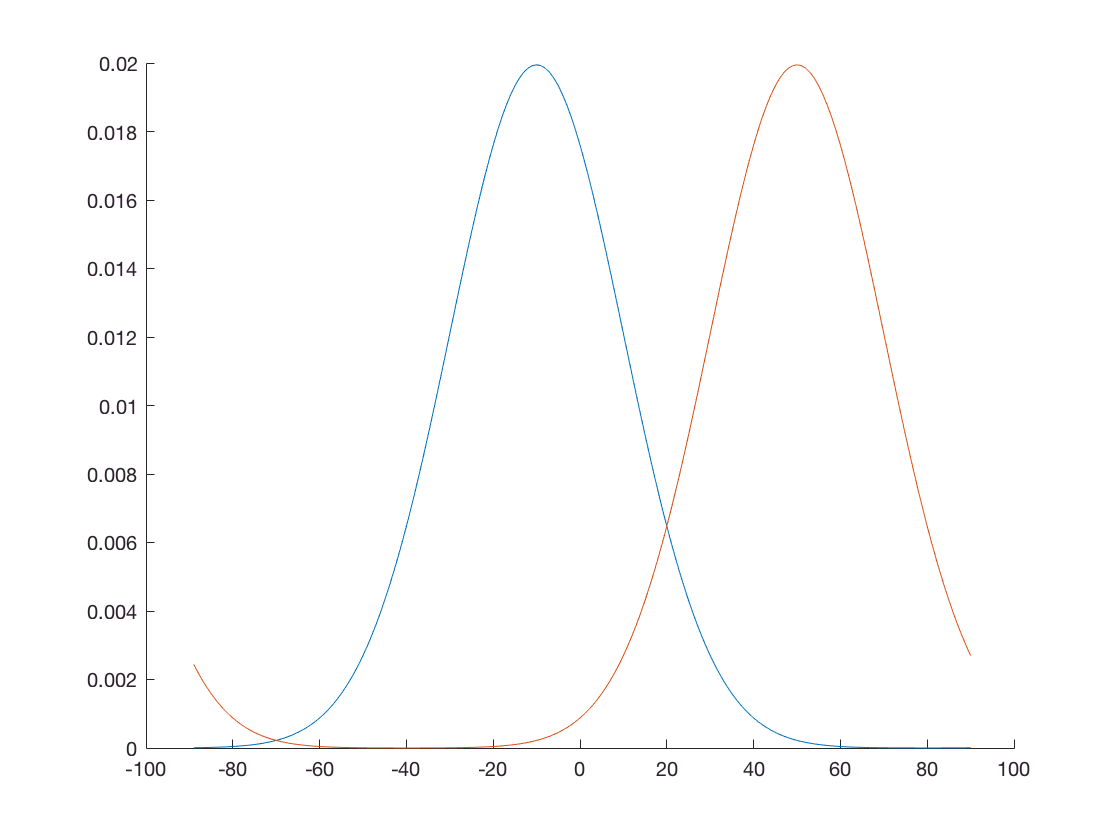

figure
hold on
plot(theta, ndata)

plot(theta, ndata_shifted)
hold off

Interpolation of raw data with weights 1:1 and 1:2

data_raw_int_1 = (data_raw + data_raw_shifted)/2;
ndata_raw_int_1_avg =  (data_raw_int_1(1:180) + data_raw_int_1(181:360))/2;
ndata_int_1 = ndata_raw_int_1_avg/sum(ndata_raw_int_1_avg);

data_raw_int_2 = (data_raw + data_raw_shifted*2)/3;
ndata_raw_int_2_avg =  (data_raw_int_2(1:180) + data_raw_int_2(181:360))/2;
ndata_int_2 = ndata_raw_int_2_avg/sum(ndata_raw_int_2_avg);

figure;
hold on
plot(theta,ndata, 'DisplayName', 'raw data set 1');
plot(theta,ndata_shifted, 'DisplayName', 'raw data set 2');
plot(theta,ndata_int_1, 'DisplayName', 'raw interpolation - 1:1 weighted');
plot(theta,ndata_int_2, 'DisplayName', 'raw interpolation - 1:2 weighted');
legend('show');
hold off

Find fourier coefficients for data 1 and data 2 

Interpolate coefficients with weight 1:1

Interpolate coefficients with weight 1:2

Compare with raw data interpolations

% Fit data to model
fs_order = 10;

% fit data 
asd = fitToFourierModel(fs_order,theta',ndata');

[fit1, G] = fitToFourierModel(fs_order,theta',ndata');
[fit2, G] = fitToFourierModel(fs_order,theta',ndata_shifted');

%% Interp coefficients
fourier_coeffs_1 = coeffvalues(fit1);
fourier_coeffs_2 = coeffvalues(fit2);

fourier_coeffs_int_1 = (fourier_coeffs_1 + fourier_coeffs_2)/2;
fourier_coeffs_int_2 = (fourier_coeffs_1 + 2*fourier_coeffs_2)/3;
C_int_1 =  (fit1.C + fit2.C)/2;
C_int_2 =  (fit1.C + 2*fit2.C)/3;

%% Evaluate Fourier equation from 1:180
interp_reconstruct_1 = evalFourier(fourier_coeffs_int_1, C_int_1, theta);
interp_reconstruct_2 = evalFourier(fourier_coeffs_int_2, C_int_2, theta);


figure
subplot(2,1,1);
hold on 
plot(theta,ndata, 'DisplayName', 'raw data set 1');
plot(theta,ndata_shifted, 'DisplayName', 'raw data set 2');
plot(theta,ndata_int_1, 'DisplayName', 'raw interpolation - 1:1 weighted');
plot(theta,ndata_int_2, 'DisplayName', 'raw interpolation - 1:2 weighted');
legend('show');
title('Raw data interpolation')
hold off

subplot(2,1,2);
hold on
plot(theta,ndata, 'DisplayName', 'raw data set 1');
plot(theta,ndata_shifted, 'DisplayName', 'raw data set 2');
plot(theta,interp_reconstruct_1, 'DisplayName', 'fourier interp - 1:1 weighted');
plot(theta,interp_reconstruct_2, 'DisplayName', 'fourier interp - 1:2 weighted');
legend('show');
title('Fourier coeff interpolation')
hold off